data = load("deepmimic-H(250mm)-step(10mm).txt");
o_data = load("processed_data_tocabi_walk.txt");

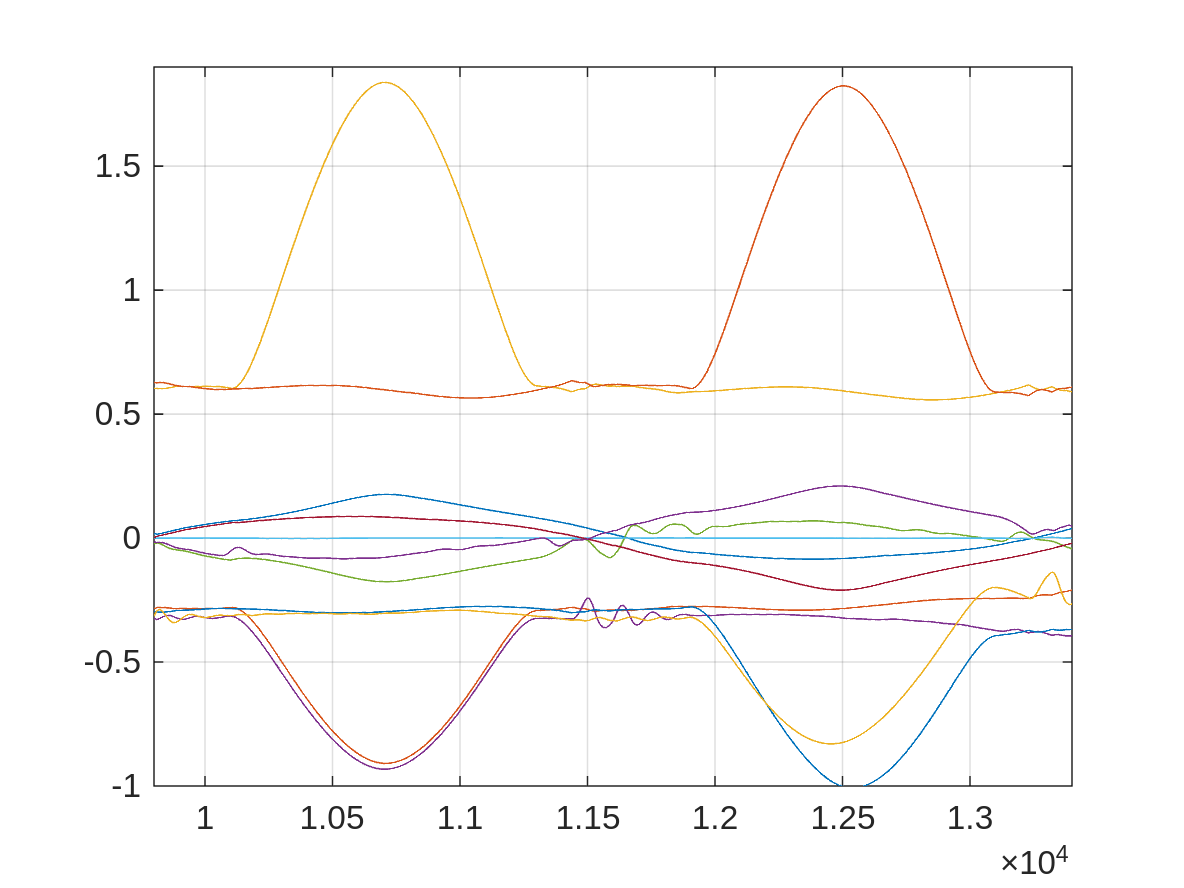

figure(1)
plot(data(:,7:17),'DisplayName','data(:,7:18)')
axis([9800 13400 -1.0 1.9])
grid on

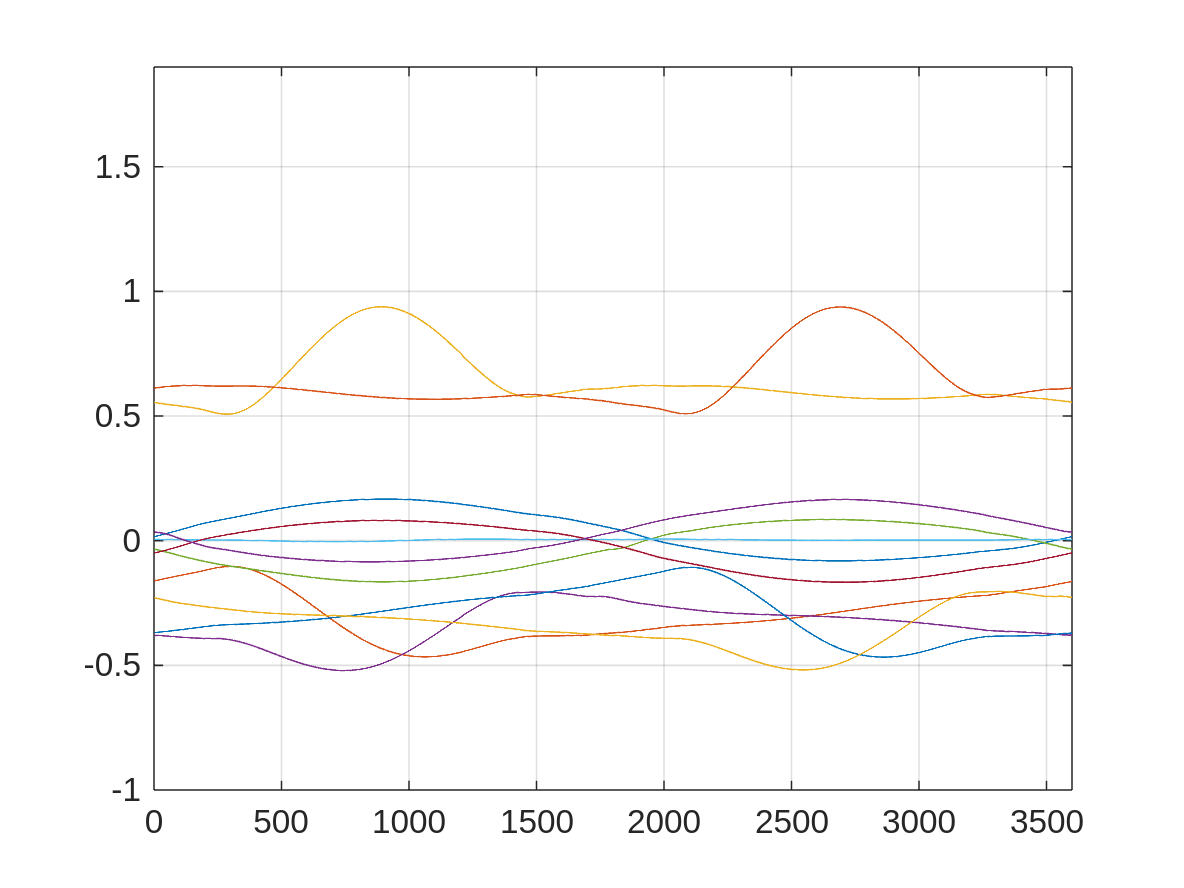

figure(2)
plot(o_data(:,3:13),'DisplayName','o_data(:,3:14)')
axis([0 3600 -1.0 1.9])
grid on

x = data(:, 7:17);
Fs = 2000

Fs = 2000

n = 6

n = 6

Wn = 8

Wn = 8

Fn=Fs/2

Fn = 1000

ftype='low'

ftype = 'low'

[b,a] = butter(n,Wn/Fn,ftype);
y = filter(b,a,x)

y =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.00

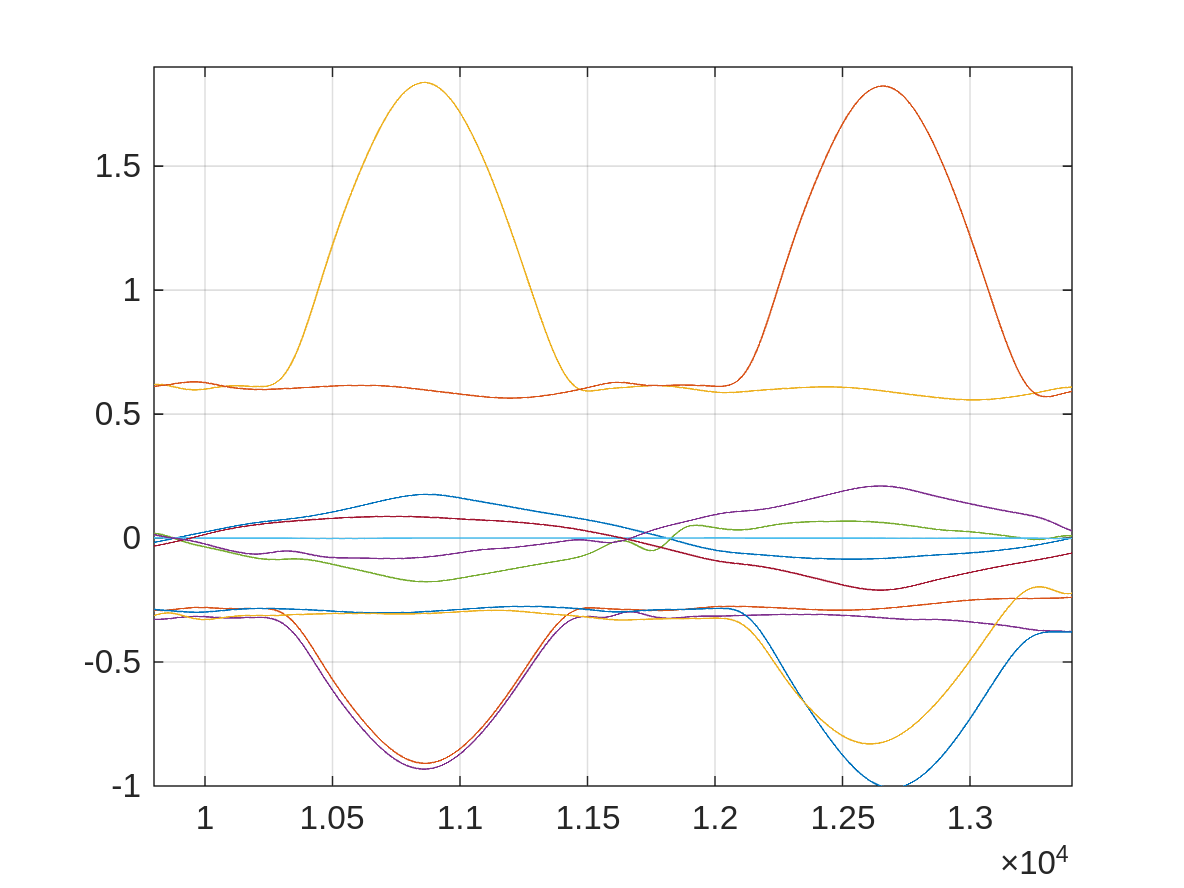

plot(y)
axis([9800 13400 -1.0 1.9])
grid on

modify_data = o_data;
modify_data(:,3:13) = y(9801:13400, :)

modify_data = 1.0e+03 *

         0   -0.0000   -0.0000   -0.0003    0.0006   -0.0003    0.0000    0.0000   -0.0000   -0.0003    0.0006   -0.0003    0.0000         0         0         0    0.0003    0.0003    0.0015   -0.0013   -0.0010         0   -0.0010         0         0         0   -0.0003   -0.0003   -0.0015    0.0013    0.0010         0    0.0010         0   -0.5099   -0.5151
    0.0000   -0.0000   -0.0000   -0.0003    0.0006   -0.0003    0.0000    0.0000   -0.0000   -0.0003    0.0006   -0.0003    0.0000         0         0         0    0.0003    0.0003    0.0015   -0.0013   -0.0010         0   -0.0010         0         0         0   -0.0003   -0.0003   -0.0015    0.0013    0.0010         0    0.0010         0   -0.5074   -0.5176
    0.0000   -0.0000   -0.0000   -0.0003    0.0006   -0.0003    0.0000    0.0000   -0.0000   -0.0003    0.0006   -0.0003    0.0000         0         0         0    0.0003    0.0003    0.0015   -0.0013   -0.0010         0   -0.0010         0         0   

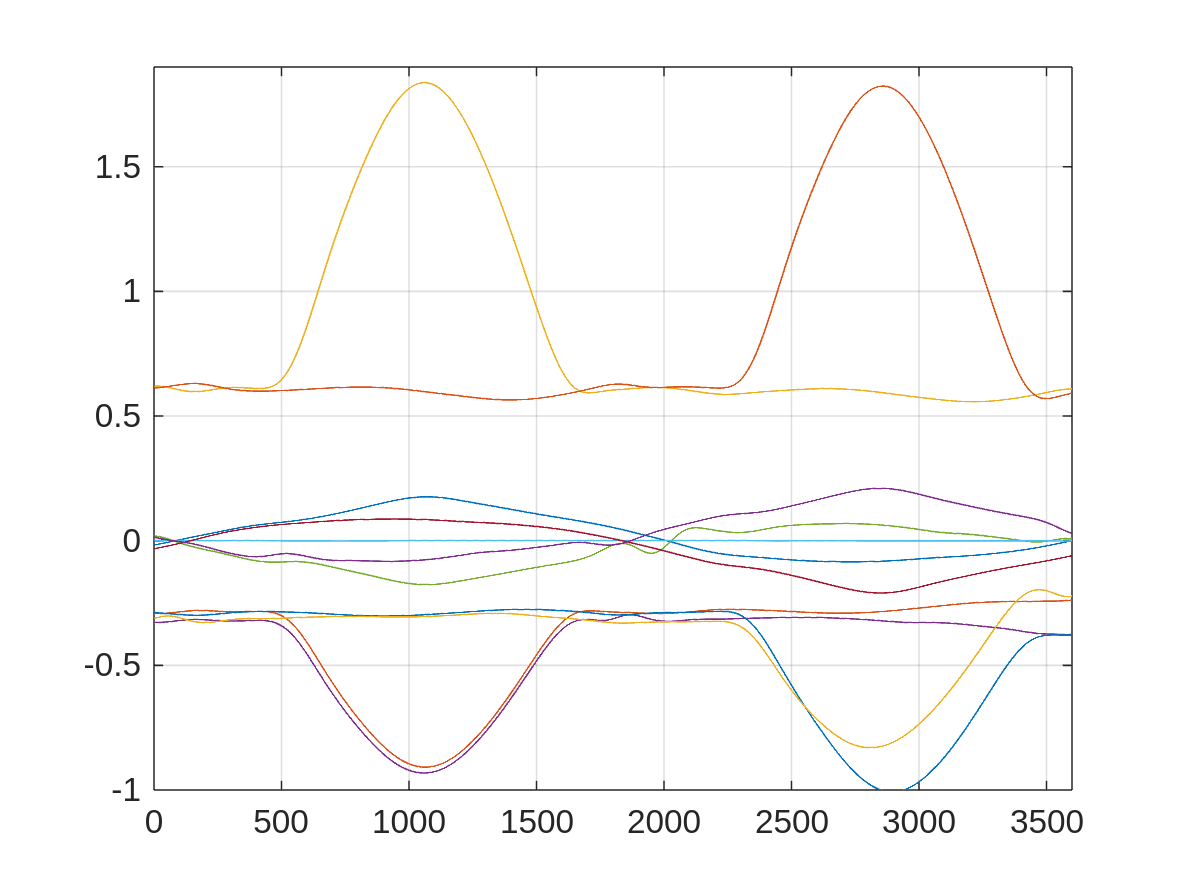

plot(modify_data(:,3:13),'DisplayName','o_data(:,3:14)')
axis([0 3600 -1.0 1.9])
grid on

writematrix(modify_data, 'FileName.txt', 'Delimiter','\t');